## Implementation Methods

Different ill-conditionde problem 

### Initialization

% cd 'F:\University\Semester IIX 2021\Detection & Estimation Theory\CA'
clear all; close all;
warning off
digits(32)
delta = eps^(2/3);

delta    is such that delta>eps but delta^2<eps, so that

H        has pseudorank == 2 in machine precision, but

H*P*H'   has pseudorank == 1 in machine precision and

H*P*H'+R is effectively singular in machine precision.

for k=1:19
  d(k) = delta*10^(10-k);

### Parameter of ill-conditioned Problem

  P  = eye(3);
  D0 = eye(3);
  U0 = eye(3);
  R  = d(k)^2*eye(2);
  H  = [1,1,1;1,1,1+d(k)];
  x0 = [1;1;-1];
  z  = H*x0 + d(k)*[randn;randn];

### Closed Form Solution

  KCF = (1/(2*d(k)*(d(k)^2+d(k)+4)))*[2*d(k)+1,d(k)-1;2*d(k)+1,d(k)-1;d(k)-2,d(k)^2+d(k)+2];
  xCF = x0 + KCF*(z - H*x0);
  PCF = (1/(8+2*d(k)*(1+d(k))))*[5+2*d(k)*(1+d(k)),-3,-2-d(k);-3,5+2*d(k)*(1+d(k)),-2-d(k);-2-d(k),-2-d(k),4+d(k)^2];

### Standard KF

  K  = P*H'/(H*P*H'+R);
  xK = x0 + K*(z - H*x0);
  PK = P - K*H*P;

### Information Filter

  xI = x0 + (H'/R)*z;
  YI = inv(P) + (H'/R)*H;
  PI = inv(YI);

### Carlson Square Filter

  z1 = z(1);
  z2 = z(2);
  H1 = H(1,:);
  H2 = H(2,:);
  R1 = R(1,1);
  R2 = R(2,2);
  C0 = utcholesky(P);
  [x1,C1] = carlson(z1,R1,H1,x0,C0);
  [x2,C2] = carlson(z2,R2,H2,x1,C1);
  PC = C2*C2';

### Comparison


  rssCF = 0; % for closed form solution
  rssK  = 0; % for Kalman solution
  rssI  = 0; % for Information solution
  rssC  = 0; % for Carlson solution
    for i=1:3
      for j=1:3
      rssCF = rssC + PCF(i,j)^2;
      if (isnan(PI(i,j)))
        PI(i,j)=0;
      end
      if (isinf(PI(i,j)))
        PI(i,j)=1e5;
      end
      if (isnan(PK(i,j)))
        PK(i,j)=0;
      end
      if (isinf(PK(i,j)))
        PK(i,j)=1e5;
      end
      if (isnan(PC(i,j)))
        PC(i,j)=0;
      end
      if (isinf(PC(i,j)))
        PC(i,j)=1e5;
      end
      rssI = rssI + (PI(i,j)  - PCF(i,j))^2;
      rssK = rssK + (PK(i,j)  - PCF(i,j))^2;
      rssC = rssC + (PC(i,j)  - PCF(i,j))^2;
      end
    end

Compute relative differences and limit rel. error to 10^4

  rdCF(k) = sqrt(rssCF/rssCF);
  rdK(k) = sqrt(rssK/rssCF);
  rdC(k) = sqrt(rssC/rssCF);
  rdI(k) = sqrt(rssI/rssCF);
end

Plot Relative Error

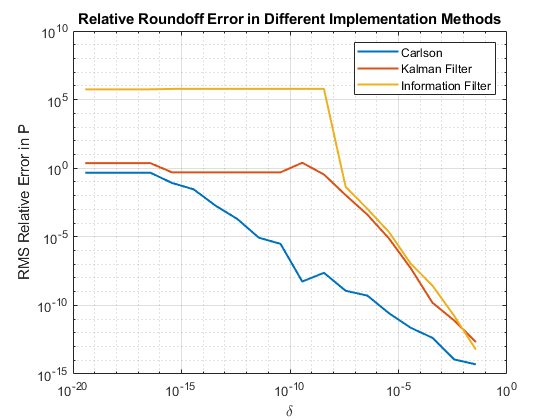

loglog(d,rdC,d,rdK,d,rdI, 'LineWidth',1.5)
grid on
title('Relative Roundoff Error in Different Implementation Methods')
ylabel('RMS Relative Error in P')
xlabel('\delta')
legend 'Carlson' 'Kalman Filter' 'Information Filter'